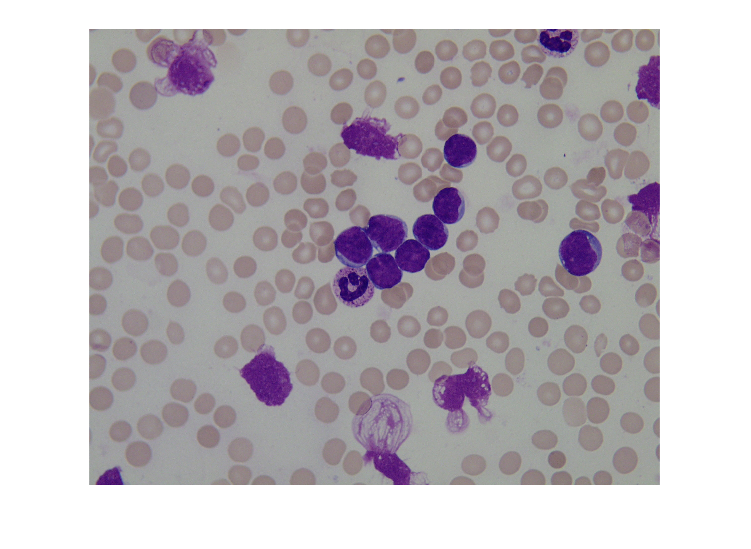

clc;
clear;
close all;
a = imread("Im001_1.jpg");
imshow(a)

hsvI = rgb2hsv(a)

hsvI = hsvI(:,:,1) =

  Columns 1 through 999

    0.9420    0.9420    0.9474    0.9474    0.9667    0.9667    0.9667    0.9667    0.9896    0.9896    0.9896    0.9896    0.0111    0.0111    0.0256    0.9722    0.8846    0.8452    0.8788    0.8611    0.8125    0.7692    0.7059    0.7083    0.6930    0.6961    0.6667    0.6389    0.6111    0.6333    0.6333    0.6333         0    0.1111    0.1111    0.0333    0.0625    0.0625    0.1389    0.1944    0.2381    0.2857    0.2879    0.2667    0.2500    0.1970    0.1667    0.1167    0.1667    0.1389    0.1875    0.1875    0.2667    0.2667    0.2667    0.2667    0.2857    0.2857    0.2333    0.2333    0.1667    0.1667    0.9167    0.9167    0.1333    0.1333    0.2000    0.2000    0.2381    0.2381    0.2857    0.2857    0.2381    0.2381    0.2000    0.1333    0.1111    0.0333         0    0.0333    0.1111    0.1667    0.1667    0.1667    0.2333    0.2333    0.2381    0.2381    0.2857    0.2857    0.2857    0.2857    0.3125    0.3125    0.3333   

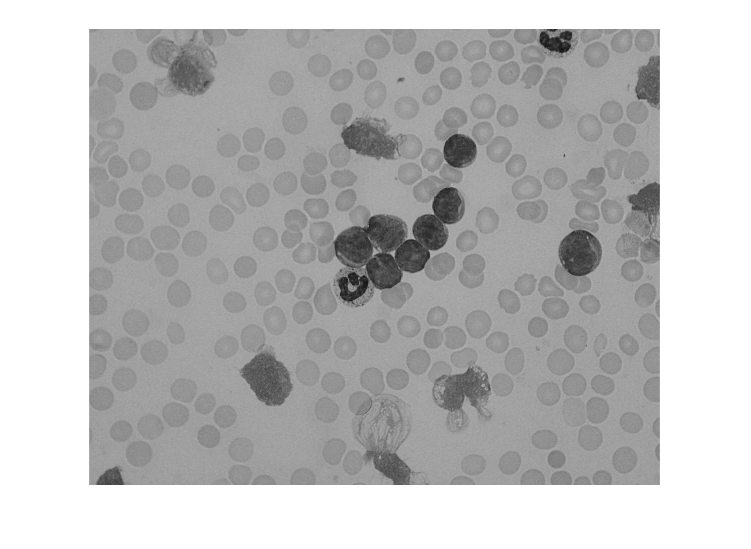

imshow(a(:,:,1))

[n m] = size(a)

n = 1368

m = 5136

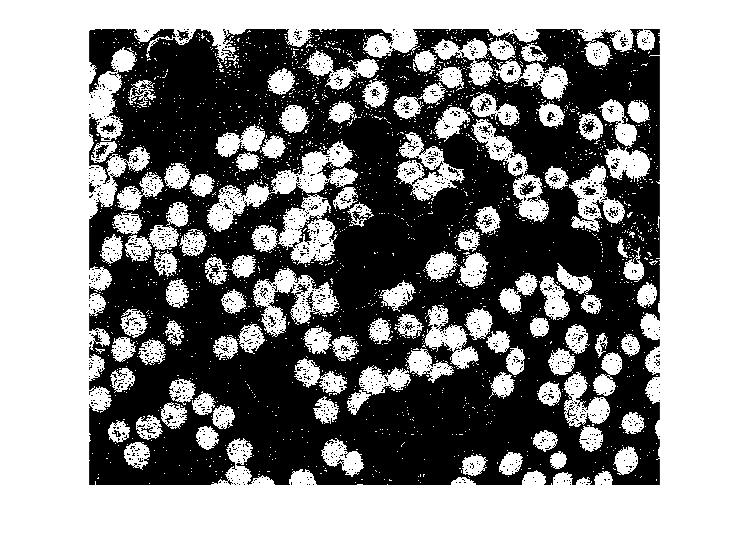

sThresh = [0.01 1];
vThresh = [0.01 1];
sThresh = [min(sThresh) max(sThresh)];
vThresh = [min(vThresh) max(vThresh)];
hueI = round(hsvI(:,:,1)*360);
satI = hsvI(:,:,2);
valI = hsvI(:,:,3);
threshI = (satI>=sThresh(1))&(satI<=sThresh(2))&(valI>=vThresh(1))&(valI<=vThresh(2));

red = ((hueI<=30)|(hueI>330))&threshI;
imshow(red)

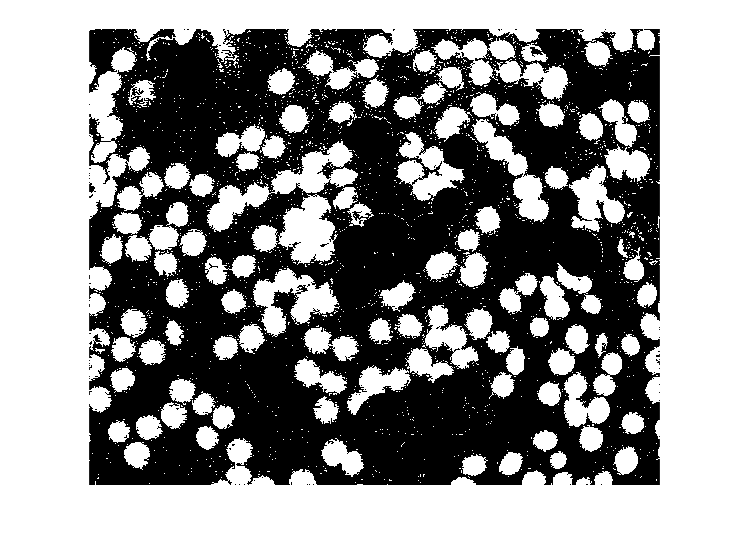

red = imfill(red,'holes');
imshow(red)